In this example we will consider the following unstable continuous time system:


$$\pmatrix{\dot{x} \cr \ddot{x}} = 
\pmatrix{0 & 1 \cr \frac{-k}{M} & 0}
\pmatrix{x \cr \dot{x}} +
\pmatrix{0 \cr \frac{1}{M}} u$$


The model corresponds to a mass spring system.

k = 1;
M = 1;
A = [0 1 ; -k/M 0];
B = [0 ; 1/M];
C = [1 0 ; 0 1];
D = [];
sys_ms_c = ss(A,B,C,D);

We will consider the data generated by the step function.

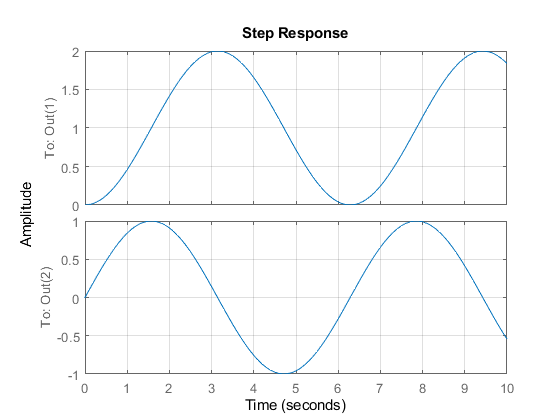

t = 0:0.1:10;
step(sys_ms_c, t)
grid on

[y_ms, t_ms, x_ms] = step(sys_ms_c, t);
U_ms = ones(1,size(t_ms,1)-1);
X_ms = x_ms.';

## Identification

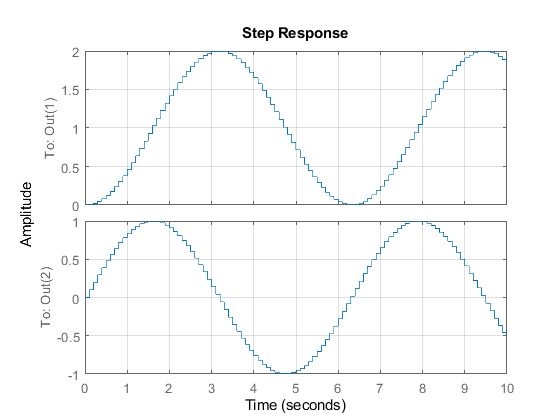

[bool, A_step, B_step] = isInformIdentification(X_ms, U_ms);
sys_step_d = ss(A_step, B_step, C, D, t(2));

step(sys_step_d, t);
grid on


sys_step_c = d2c(sys_step_d)

sys_step_c =
 
  A = 
              x1         x2
   x1  1.145e-15          1
   x2         -1  5.516e-15
 
  B = 
               u1
   x1  -1.492e-15
   x2           1
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



## Controllability

disp('Is the data informative for controllability?')

Is the data informative for controllability?


isInformControllable(X_ms)

ans = logical
   1


## Stabilisability

disp('Is the data informative for stabilisability?')

Is the data informative for stabilisability?


isInformStabilisable(X_ms)

ans = logical
   1


## State feedback controller

disp('Is the data informative for state feedback?')

Is the data informative for state feedback?


[bool, K] = StateFeedbackYalmip(X_ms, U_ms)

bool = logical
   0



K =

     []



if bool
    abs(eig(A_step))
    abs(eig(A_step-B_step*K))
end

## Deadbeat control

[bool, K] = isInformDeadbeatControl(X_ms, U_ms)

bool = logical
   1


K =   -99.0834  -14.9750



eig(A_step + B_step * K)

ans = 	1.0e+-6 *

   0.0000 + 0.2355i
   0.0000 - 0.2355i



eig(A + B * K)

ans =   -7.4875 + 6.6348i
  -7.4875 - 6.6348i
